# CDL Channel Model Customization with Ray Tracing

This version using UE_grid{idx_grid}.channel{idx_point} in the loop (to save each channel object to UE_grid

The other version just use channel in the loop

This example shows how to customize the CDL channel model parameters by using the output of a ray tracing analysis. The example shows how to: 

- Specify the location of a transmitter and a receiver in a 3D environment.

- Use ray tracing to calculate the geometric aspects of the channel: number of rays, angles, delays and attenuations.

- Configure the CDL channel model with the result of ray tracing analysis.

- Specify the channel antenna arrays using Phased Array System Toolbox™.

- Visualize the transmit and receive array radiation patterns based on singular value decomposition of a perfect channel estimate.

% Change the current folder to the folder of this file.
if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end

addpath('helper')
addpath('osmFile')

## Base Station and UE Configuration

The example assumes that both the base station and the UE use rectangular arrays. The array orientations are specified as a pair of values representing azimuth and elevation. Both angles are in degrees.

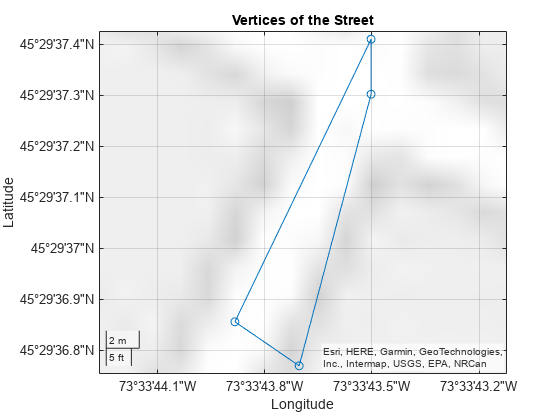

UE_grid = cell(1,2);
UE_grid{1}.street = 'Peel'; 
    UE_grid{1}.vertice{1}.location = [45.493695,-73.562033]; % lat, lon
    UE_grid{1}.vertice{2}.location = [45.493725,-73.562084];
    UE_grid{1}.vertice{3}.location = [45.493571,-73.562190];
    UE_grid{1}.vertice{4}.location = [45.493547,-73.562140];
% UE_grid{2}.street = 'William'; 
%     UE_grid{2}.vertice{1}.location = [45.495371,-73.560918];
%     UE_grid{2}.vertice{2}.location = [45.495328,-73.560852];
%     UE_grid{2}.vertice{3}.location = [45.495774,-73.560438];
%     UE_grid{2}.vertice{4}.location = [45.495785,-73.560452];

% Extract coordinates from UE_grid
latitudes = [UE_grid{1}.vertice{1}.location(1), UE_grid{1}.vertice{2}.location(1), ...
             UE_grid{1}.vertice{3}.location(1), UE_grid{1}.vertice{4}.location(1), ...
             UE_grid{1}.vertice{1}.location(1)]; % Closing the loop
longitudes = [UE_grid{1}.vertice{2}.location(2), UE_grid{1}.vertice{2}.location(2), ...
              UE_grid{1}.vertice{3}.location(2), UE_grid{1}.vertice{4}.location(2), ...
              UE_grid{1}.vertice{2}.location(2)]; % Closing the loop

% Create a geographic plot
figure;
geoplot(latitudes, longitudes, '-o');
title('Vertices of the Street');
grid on;

## Import and Visualize 3-D Environment with Buildings for Ray Tracing

Launch Site Viewer with buildings in ETS. For more information about the osm file, see [1].

if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","map.osm");    
end

## Create Base Station and UE

Locate the base station and the UE on the map.

fc = 60e9;                             % carrier frequency (Hz)  2.4e9 2.6e9?
bsPosition = [45.494945,-73.561361];  % lat, lon
bsAntSize = [1 1]; % [8 8];                    % number of rows and columns in rectangular array (base station)
bsArrayOrientation = [-30 0].';       % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards) in deg

reflectionsOrder = 1;                 % number of reflections for ray tracing analysis (0 for LOS)
 
% Bandwidth configuration, required to set the channel sampling rate and for perfect channel estimation
SCS = 30; % 15; % subcarrier spacing
NRB = 51; % number of resource blocks, SCS*NRB*12 MHz bandwidth for transmission

bsSite = txsite("Name","Base station", ...
    "Latitude",bsPosition(1),"Longitude",bsPosition(2),...
    "AntennaAngle",bsArrayOrientation(1:2),...
    "AntennaHeight",4,...  % in m
    "TransmitterFrequency",fc);
show(bsSite);

Plot the vertices

ueArrayOrientation = [180 45].';
pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
    i=1;
% for idx_grid = 1 %1:length(UE_grid)
%     for idx_vertex = 1:4
%         ueSite = rxsite("Name",['UE', num2str(i)], ...
%             "Latitude",UE_grid{idx_grid}.vertice{idx_vertex}.location(1),"Longitude",UE_grid{idx_grid}.vertice{idx_vertex}.location(2),...
%             "AntennaHeight",1,... % in m
%             "AntennaAngle",ueArrayOrientation(1:2));
%         show(ueSite);
%         rays1 = raytrace(bsSite,ueSite,pm,"Type","pathloss");
%         plot(rays1{1})
%         i=i+1;
%     end
% end

UE_grid{1}.pointInside = gen_pointInside(UE_grid{1}, 1, 1); % in Peel street

idx_save = check_save_idx(['Data/',num2str(0),'dB'], '_mapBaseData')

idx_save = 1

ueAntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg
pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
c = physconst('LightSpeed');
lambda = c/fc;
ofdmInfo = nrOFDMInfo(NRB,SCS);
[txWaveform, carrier, dmrsSymbols, dmrsIndices] = wave_gen();

% UE array (single panel)
ueArray = phased.NRRectangularPanelArray('Size',[ueAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
ueArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element
% Base station array (single panel)
bsArray = phased.NRRectangularPanelArray('Size',[bsAntSize(1:2) 1 1],'Spacing', [0.5*lambda*[1 1] 1 1]);
bsArray.ElementSet = {phased.IsotropicAntennaElement};   % isotropic antenna element;  {phased.NRAntennaElement('PolarizationAngle',-45) phased.NRAntennaElement('PolarizationAngle',45)}; % cross polarized elements

num_UE = 0; % total number of UEs
for idx_grid = 1 % 1:length(UE_grid)
    num_UE = num_UE + size(UE_grid{idx_grid}.pointInside,1);
end


SNRdB = 0; % 0:5:30; 
for snr = SNRdB
    fprintf('SNR: %d / %d', snr, SNRdB(end));
    SNR = 10^(snr/10); % Calculate linear SNR
    N0 = 1/sqrt(2*double(ofdmInfo.Nfft)*SNR); % simParameters.NRxAnts = 1

    H_true      = zeros(14,612,num_UE);    % symbol x subc x num_UE
    Y           = zeros(14,612,num_UE);
    H_equalized = zeros(14,612,num_UE);
    H_linear    = zeros(14,612,num_UE);
    % H_practical = zeros(14,612,num_UE);     % channel estimated by Matlab built-in
    Y_data = []; % symbol x subc x 2 x num_UE
    H_data = [];
    H_equalized_data = [];
    H_linear_data = [];

    idx_UE = 1;

    for idx_grid = 1 %  1:length(UE_grid)
        for idx_point = 1:size(UE_grid{idx_grid}.pointInside,1)
            % UEs
            uePosition = UE_grid{idx_grid}.pointInside(idx_point,:); % lat, lon
            ueSite = rxsite("Name",['UE', num2str(idx_point)], ...
                "Latitude",uePosition(1),"Longitude",uePosition(2),...
                "AntennaHeight",1,... % in m
                "AntennaAngle",ueArrayOrientation(1:2));
            UE_grid{idx_grid}.rays{idx_point} = raytrace(bsSite,ueSite,pm,"Type","pathloss");
        
            show(ueSite);
            plot(UE_grid{idx_grid}.rays{idx_point}{1})

            % temp variables
            pathToAs = [UE_grid{idx_grid}.rays{idx_point}{1}.PropagationDelay]-min([UE_grid{idx_grid}.rays{idx_point}{1}.PropagationDelay]);  % Time of arrival of each ray (normalized to 0 sec)
            avgPathGains  = -[UE_grid{idx_grid}.rays{idx_point}{1}.PathLoss];                                    % Average path gains of each ray
            pathAoDs = [UE_grid{idx_grid}.rays{idx_point}{1}.AngleOfDeparture];                                  % AoD of each ray
            pathAoAs = [UE_grid{idx_grid}.rays{idx_point}{1}.AngleOfArrival];                                    % AoA of each ray
            isLOS = any([UE_grid{idx_grid}.rays{idx_point}{1}.LineOfSight]);                                     % Line of sight flag
            if ~isLOS
                error("Should be LOS");  % stop checking
            end

            UE_grid{idx_grid}.channel{idx_point} = nrCDLChannel;
            UE_grid{idx_grid}.channel{idx_point}.DelayProfile = 'Custom';
            UE_grid{idx_grid}.channel{idx_point}.PathDelays = pathToAs;
            UE_grid{idx_grid}.channel{idx_point}.AveragePathGains = avgPathGains;
            UE_grid{idx_grid}.channel{idx_point}.AnglesAoD = pathAoDs(1,:);       % azimuth of departure
            UE_grid{idx_grid}.channel{idx_point}.AnglesZoD = 90-pathAoDs(2,:);    % channel uses zenith angle, rays use elevation
            UE_grid{idx_grid}.channel{idx_point}.AnglesAoA = pathAoAs(1,:);       % azimuth of arrival
            UE_grid{idx_grid}.channel{idx_point}.AnglesZoA = 90-pathAoAs(2,:);    % channel uses zenith angle, rays use elevation
            UE_grid{idx_grid}.channel{idx_point}.HasLOSCluster = isLOS;
            UE_grid{idx_grid}.channel{idx_point}.CarrierFrequency = fc;
            UE_grid{idx_grid}.channel{idx_point}.NormalizeChannelOutputs = false; % do not normalize by the number of receive antennas, this would change the receive power
            UE_grid{idx_grid}.channel{idx_point}.NormalizePathGains = false;      % set to false to retain the path gains
                
            UE_grid{idx_grid}.channel{idx_point}.ReceiveAntennaArray = ueArray;
            UE_grid{idx_grid}.channel{idx_point}.ReceiveArrayOrientation = [ueArrayOrientation(1); (-1)*ueArrayOrientation(2); 0];  % the (-1) converts elevation to downtilt
            
            UE_grid{idx_grid}.channel{idx_point}.TransmitAntennaArray = bsArray;
            UE_grid{idx_grid}.channel{idx_point}.TransmitArrayOrientation = [bsArrayOrientation(1); (-1)*bsArrayOrientation(2); 0];   % the (-1) converts elevation to downtilt
    
            UE_grid{idx_grid}.channel{idx_point}.SampleRate = ofdmInfo.SampleRate;
        
            UE_grid{idx_grid}.channel{idx_point}.ChannelFiltering = true;
            [rxWaveform,pathGains,sampleTimes] = UE_grid{idx_grid}.channel{idx_point}(txWaveform);
            
            % approach 1
            % noise = N0*complex(randn(size(rxWaveform)), randn(size(rxWaveform)));
            % rxWaveform1 = rxWaveform + noise;
            % approach 2 
            rxWaveform =  awgn(rxWaveform,snr,'measured');
            rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
            Y(:,:,idx_UE) = rxGrid'; % 14x612

            % approach 3
            % rxGrid1 = nrOFDMDemodulate(carrier,rxWaveform);
            % rxGrid1  = awgn(rxGrid(:,:,idx_UE),snr,'measured');
            % Y(:,:,idx_UE) = rxGrid'; % 14x612
    
            % H_LS and H_LI
                % [H_equalized_n1, H_linear_n1] = Lin_Interpolate(rxGrid1, dmrsIndices, dmrsSymbols);
                % 612x14
            [H_equalized_n, H_linear_n] = Lin_Interpolate(rxGrid, dmrsIndices, dmrsSymbols);

            H_equalized(:,:,idx_UE) = H_equalized_n';  % 14x612
            H_linear(:,:,idx_UE)    = H_linear_n';     % 14x612
    
            % H_practical (channel estimation by Matlab built-in)
            % H_practical(:,:,idx,anten_bs) = nrChannelEstimate(rxGrid, pilot_Indices, pilot_Symbols);

            % H_true
            % Get path filters for perfect channel estimation
            pathFilters = getPathFilters(UE_grid{idx_grid}.channel{idx_point});
            [offset,~] = nrPerfectTimingEstimate(pathGains,pathFilters);
            rxWaveform = rxWaveform(1+offset:end, :);
            H_true_n = nrPerfectChannelEstimate(carrier,pathGains, ...
                pathFilters,offset,sampleTimes);
                % 612x14
            H_true(:,:,idx_UE) = H_true_n'; % 14x612

            idx_UE = idx_UE + 1;
            if mod(idx_UE,200)==0
                fprintf('UE no %d / %d \n', idx_UE, num_UE);
            end
        end
    end
end

SNR: 0 / 0

Data in Grid 1

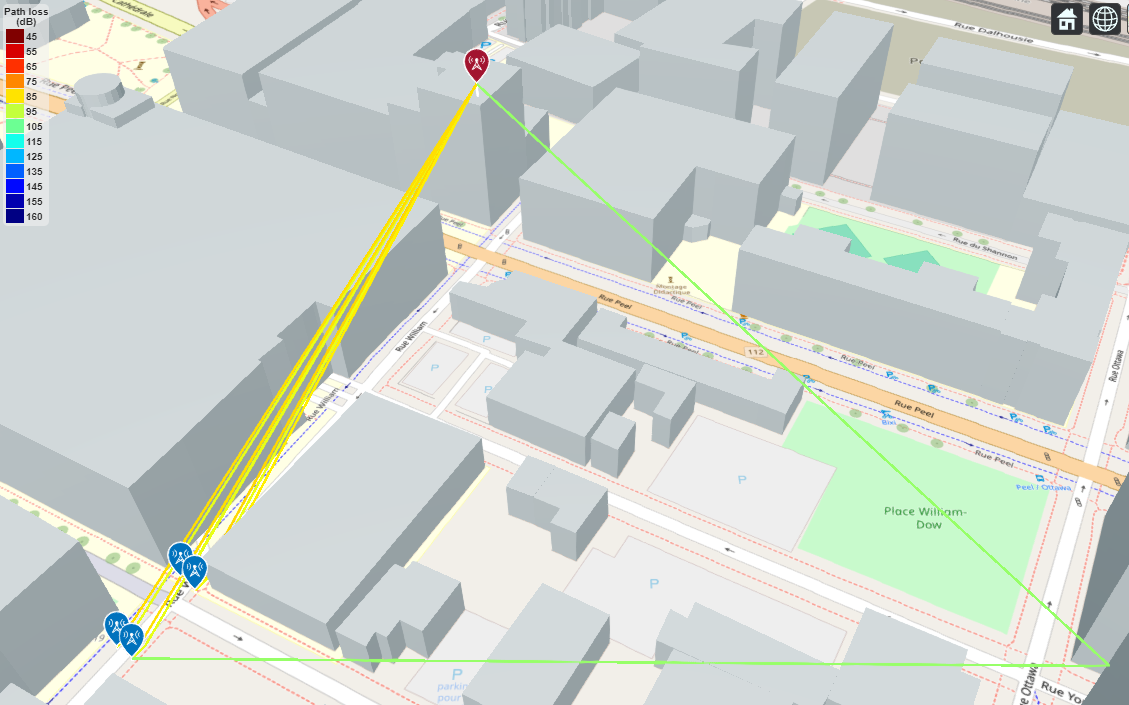

--> the lower the carrier frequency, the less multipath affects the path loss

(lower the carrier frequency, the smaller the path loss, and the less chance of frequency-selective fading, and the more chance of flat fading)

size(H_true)

ans =     14   612     4


min(min(min(min(real(H_true(:,:,1:(size(H_true,3)/2) )), imag(H_true(:,:,1:(size(H_true,3)/2) ))) )))

ans = -6.9202e-06

max(max(max( min(real(H_true(:,:,1:(size(H_true,3)/2) )), imag(H_true(:,:,1:(size(H_true,3)/2) ))) )))

ans = 1.0973e-05

mean(mean(mean( min(real(H_true(:,:,1:(size(H_true,3)/2) )), imag(H_true(:,:,1:(size(H_true,3)/2) ))) )))

ans = 2.6665e-08

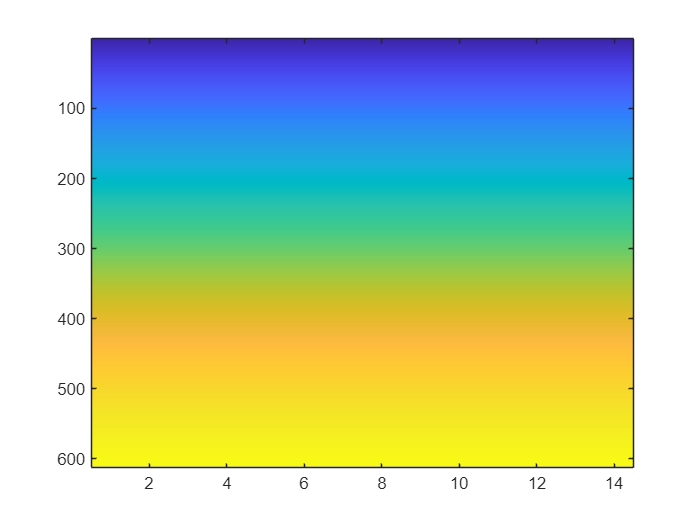

imagesc(real(H_true(:,:,1))')

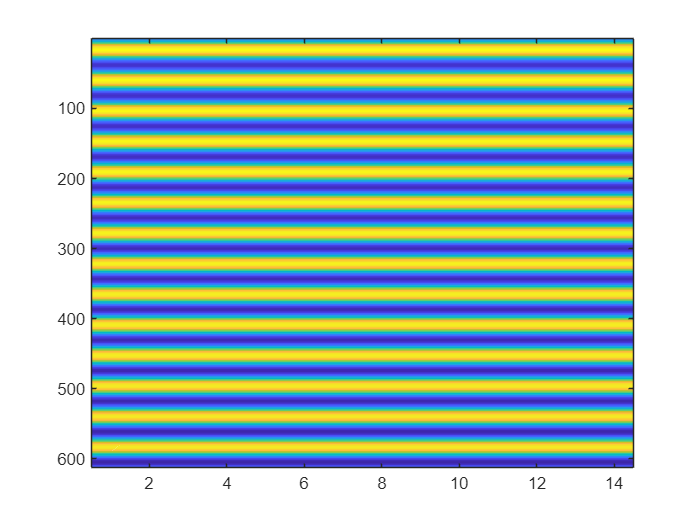

imagesc(imag(H_true(:,:,2))')

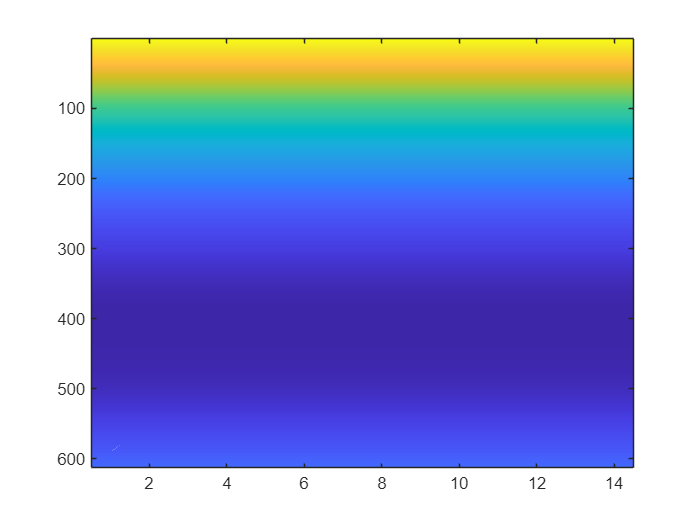

imagesc(real(H_true(:,:,3))')

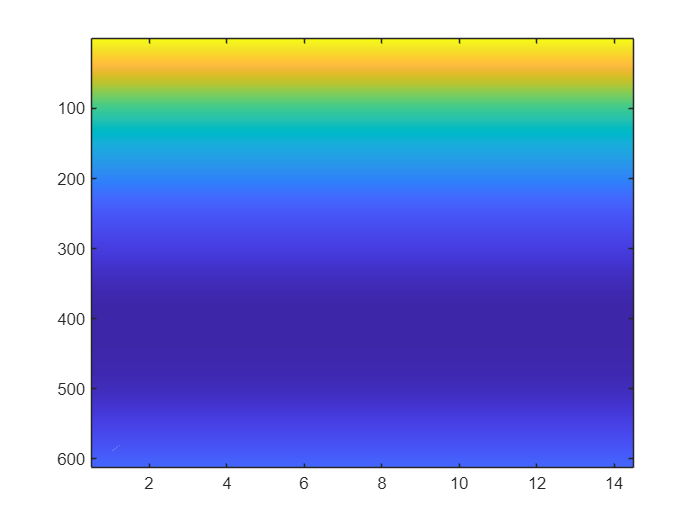

imagesc(real(H_true(:,:,4))')

% imagesc(real(H_true(:,:,300))')